clear;
close all;


## Importação dos dados

addpath('covid19pt-data/')
amostras = readtable('amostras.csv');
amostras.data = datetime(amostras.data, 'InputFormat','d-MM-uuuu');
%plot(amostras.data, amostras.amostras)
casos = readtable('data.csv');
casos.data = datetime(casos.data, 'InputFormat','d-MM-uuuu');
casos.data_dados = datetime(casos.data_dados, 'InputFormat','d-MM-uuuu HH:mm');
casos([1,2,3,4,size(casos,1)],:) = [];

- Contém dados até ao dia:

disp(casos.data_dados(size(casos,1)))

   02-Jan-2022



## Tratamento dos Dados

### Casos confirmados de covid-19:

- Evolução Diária dos casos

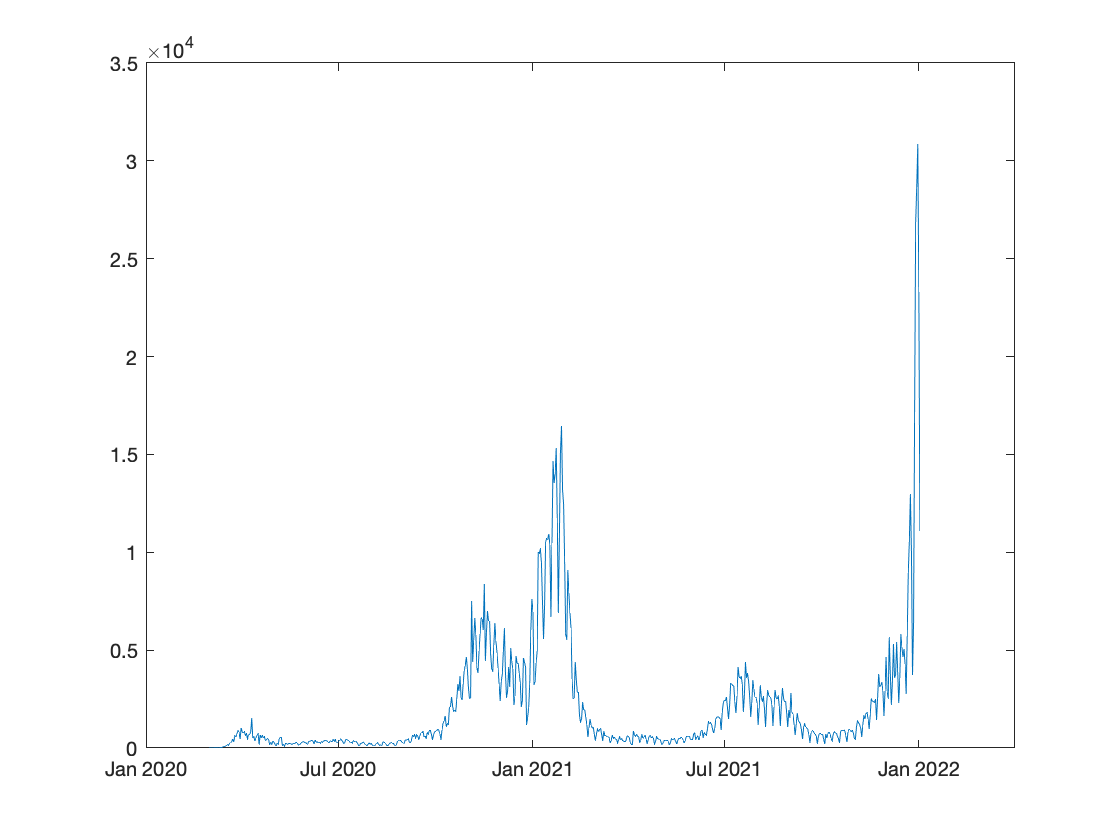

plot(casos.data, casos.confirmados_novos)

- Análise da percentagem de amostras positivas

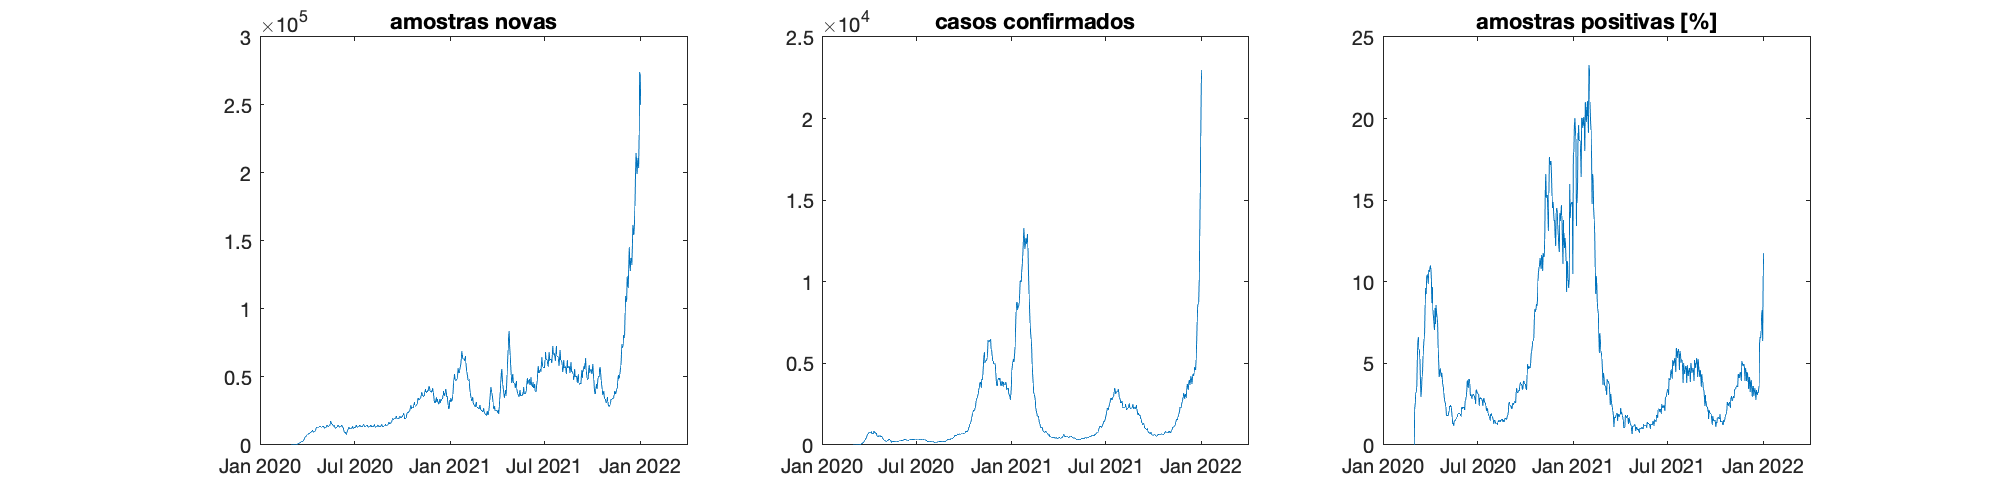

casos_positivos = (casos.confirmados_novos ./ amostras.amostras_novas);
f = figure();
subplot(1,3,1);
plot(amostras.data, movavg(amostras.amostras_novas, 'simple', 6));
title('amostras novas');
subplot(1,3,2);
plot(amostras.data, movavg(casos.confirmados_novos, 'simple', 6));
title('casos confirmados');
subplot(1,3,3);
plot(amostras.data, movavg(casos_positivos*100, 'simple', 6));
title('amostras positivas [%]');
set(f, 'Position', [0 0 1000 250])

- Evolução Diária dos internados em UCI

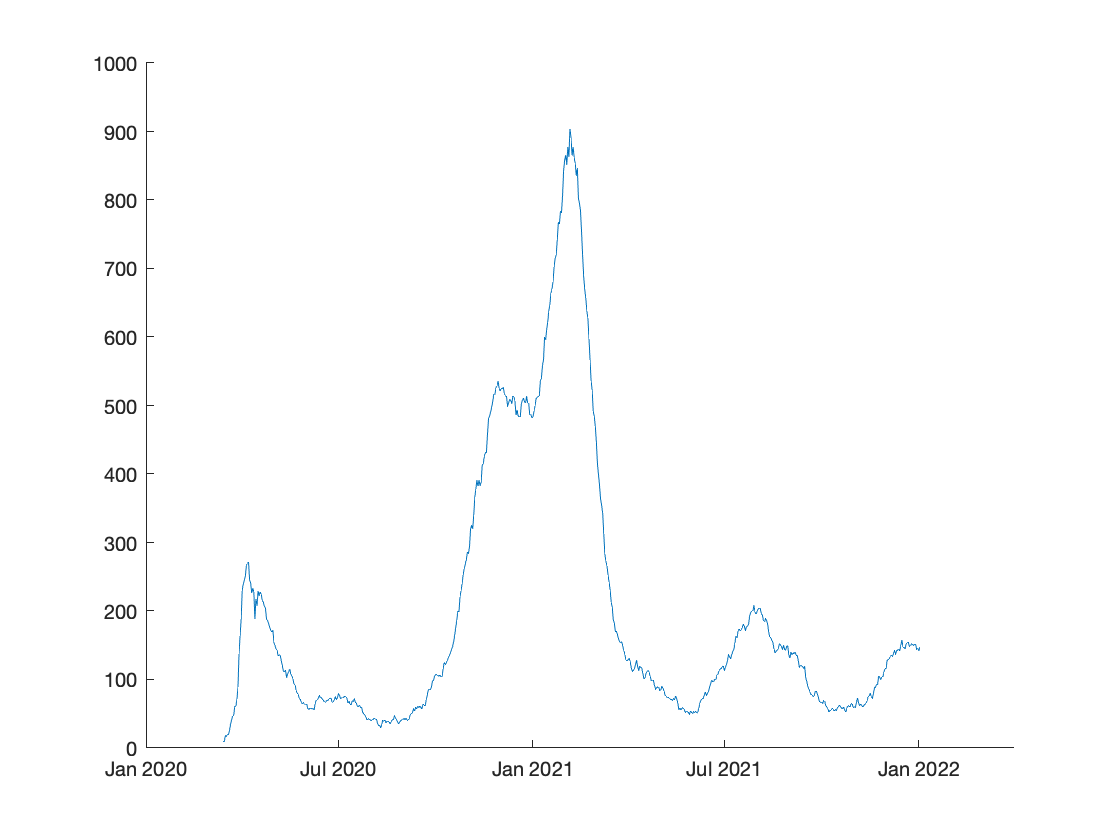

figure();
%internados = (casos.internados_uci ./ amostras.amostras_novas);
hold on
plot(amostras.data, casos.internados_uci);
%plot(amostras.data, casos.confirmados_novos);
hold off

### Análise dos internamentos por covid-19:

- Sobreposição de internados em cuidados intensivos com o número de casos confirmados

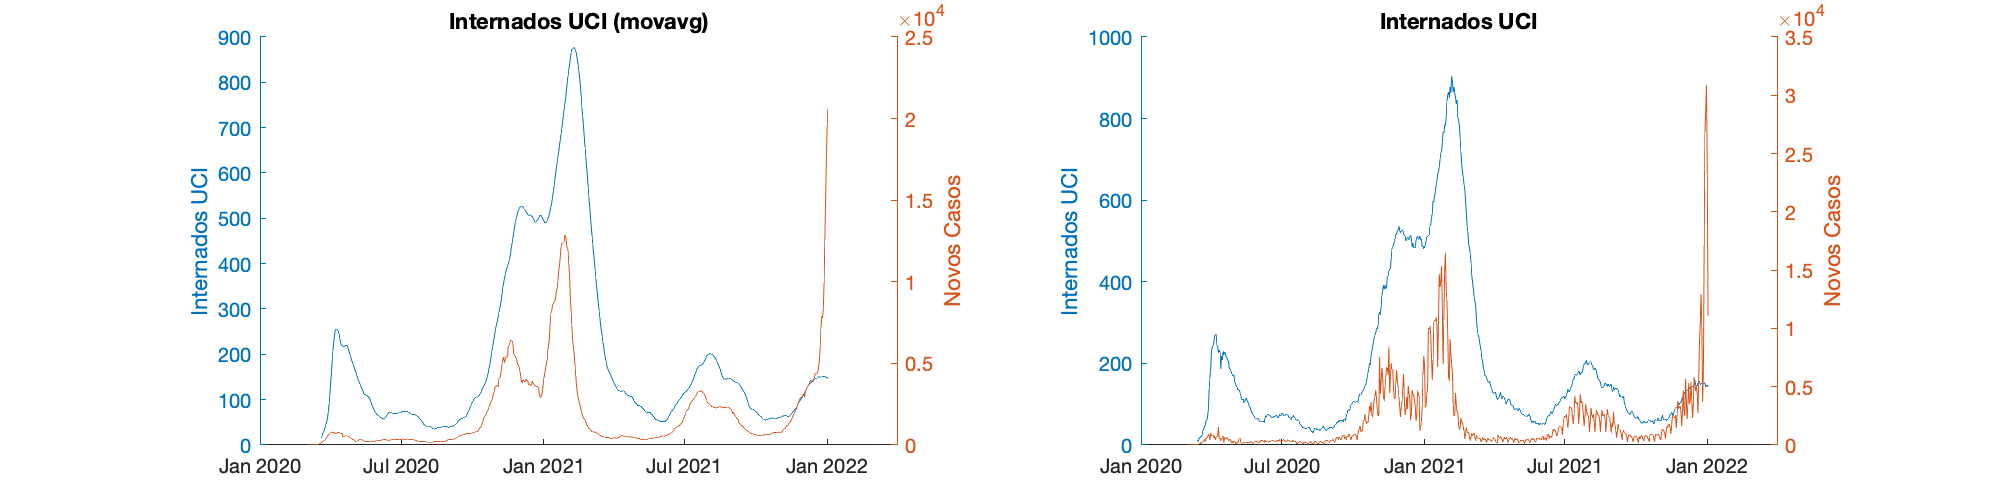


f1 = figure();
%internados = (casos.internados_uci ./ amostras.amostras_novas);
subplot(1,2,1);
hold on
    title('Internados UCI (movavg)');
    yyaxis left;
    ylabel('Internados UCI');
    plot(amostras.data, movavg(casos.internados_uci, 'simple', 7));
    yyaxis right;
    ylabel('Novos Casos');
    plot(amostras.data, movavg(casos.confirmados_novos, 'simple', 7));
hold off;
subplot(1,2,2);
hold on;
    title('Internados UCI');
    yyaxis left;
    ylabel('Internados UCI');
    plot(amostras.data, casos.internados_uci);
    yyaxis right;
    ylabel('Novos Casos');
    plot(amostras.data, casos.confirmados_novos);
hold off;
set(f1, 'Position', [0 0 1000 250])

- Percentagem de internados dos casos ativos

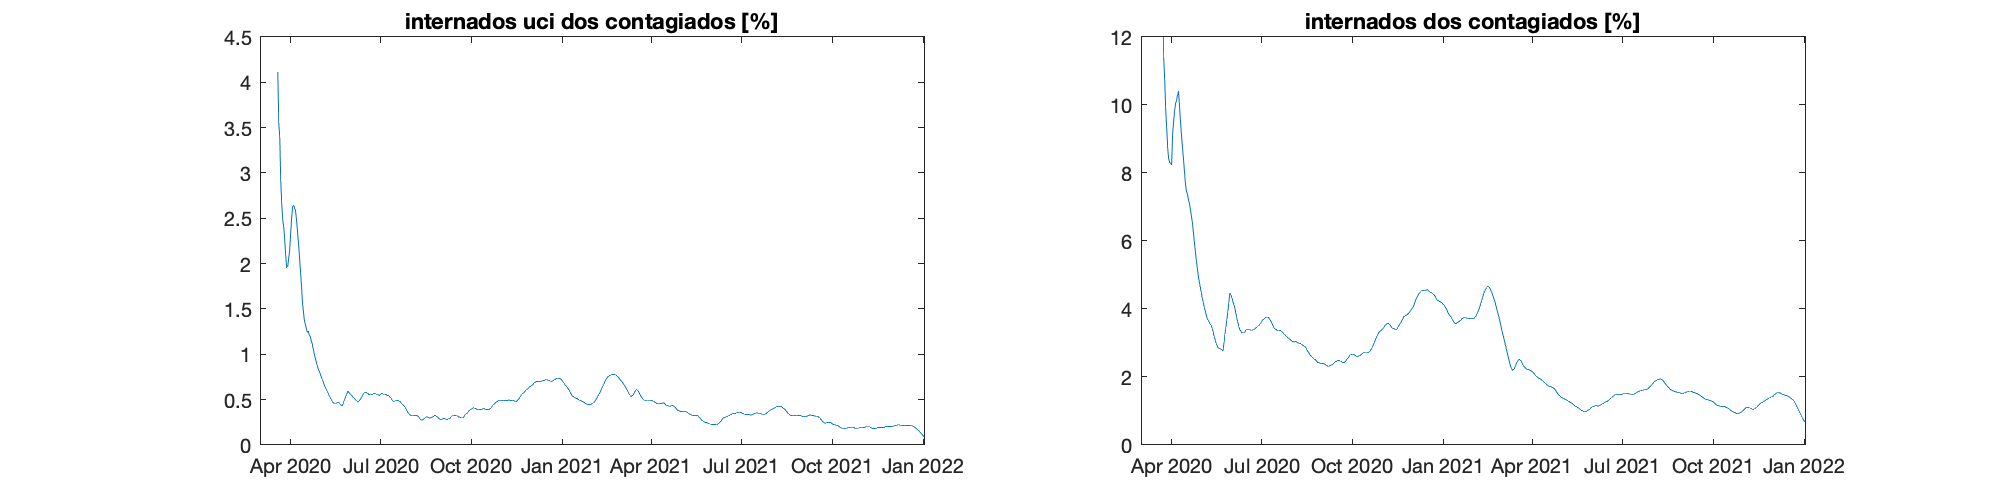

f5 = figure();
subplot(1,2,1);
internados_uci = (casos.internados_uci ./ casos.ativos);
plot(amostras.data, movavg(internados_uci*100, 'simple', 6));
title('internados uci dos contagiados [%]');
xlim([amostras.data(1) amostras.data(size(amostras.data, 1))])
subplot(1,2,2);
internados = (casos.internados ./ casos.ativos);
plot(amostras.data, movavg(internados*100, 'simple', 7));
title('internados dos contagiados [%]');
xlim([amostras.data(1) amostras.data(size(amostras.data, 1))])
ylim([0 12]);
set(f5, 'Position', [0 0 1000 250])

- Por inspeção dos dados é possível observar que novos casos apenas se traduzem em internamentos após, em média, 9 dias. Para analisar então a reação dos portugueses aos contágios traçam-se então os gráficos apresentados de seguida, tendo sido aplicado um offset de 9 dias aos internamentos (para um x -> internados(x+9) e novos_casos(x)).

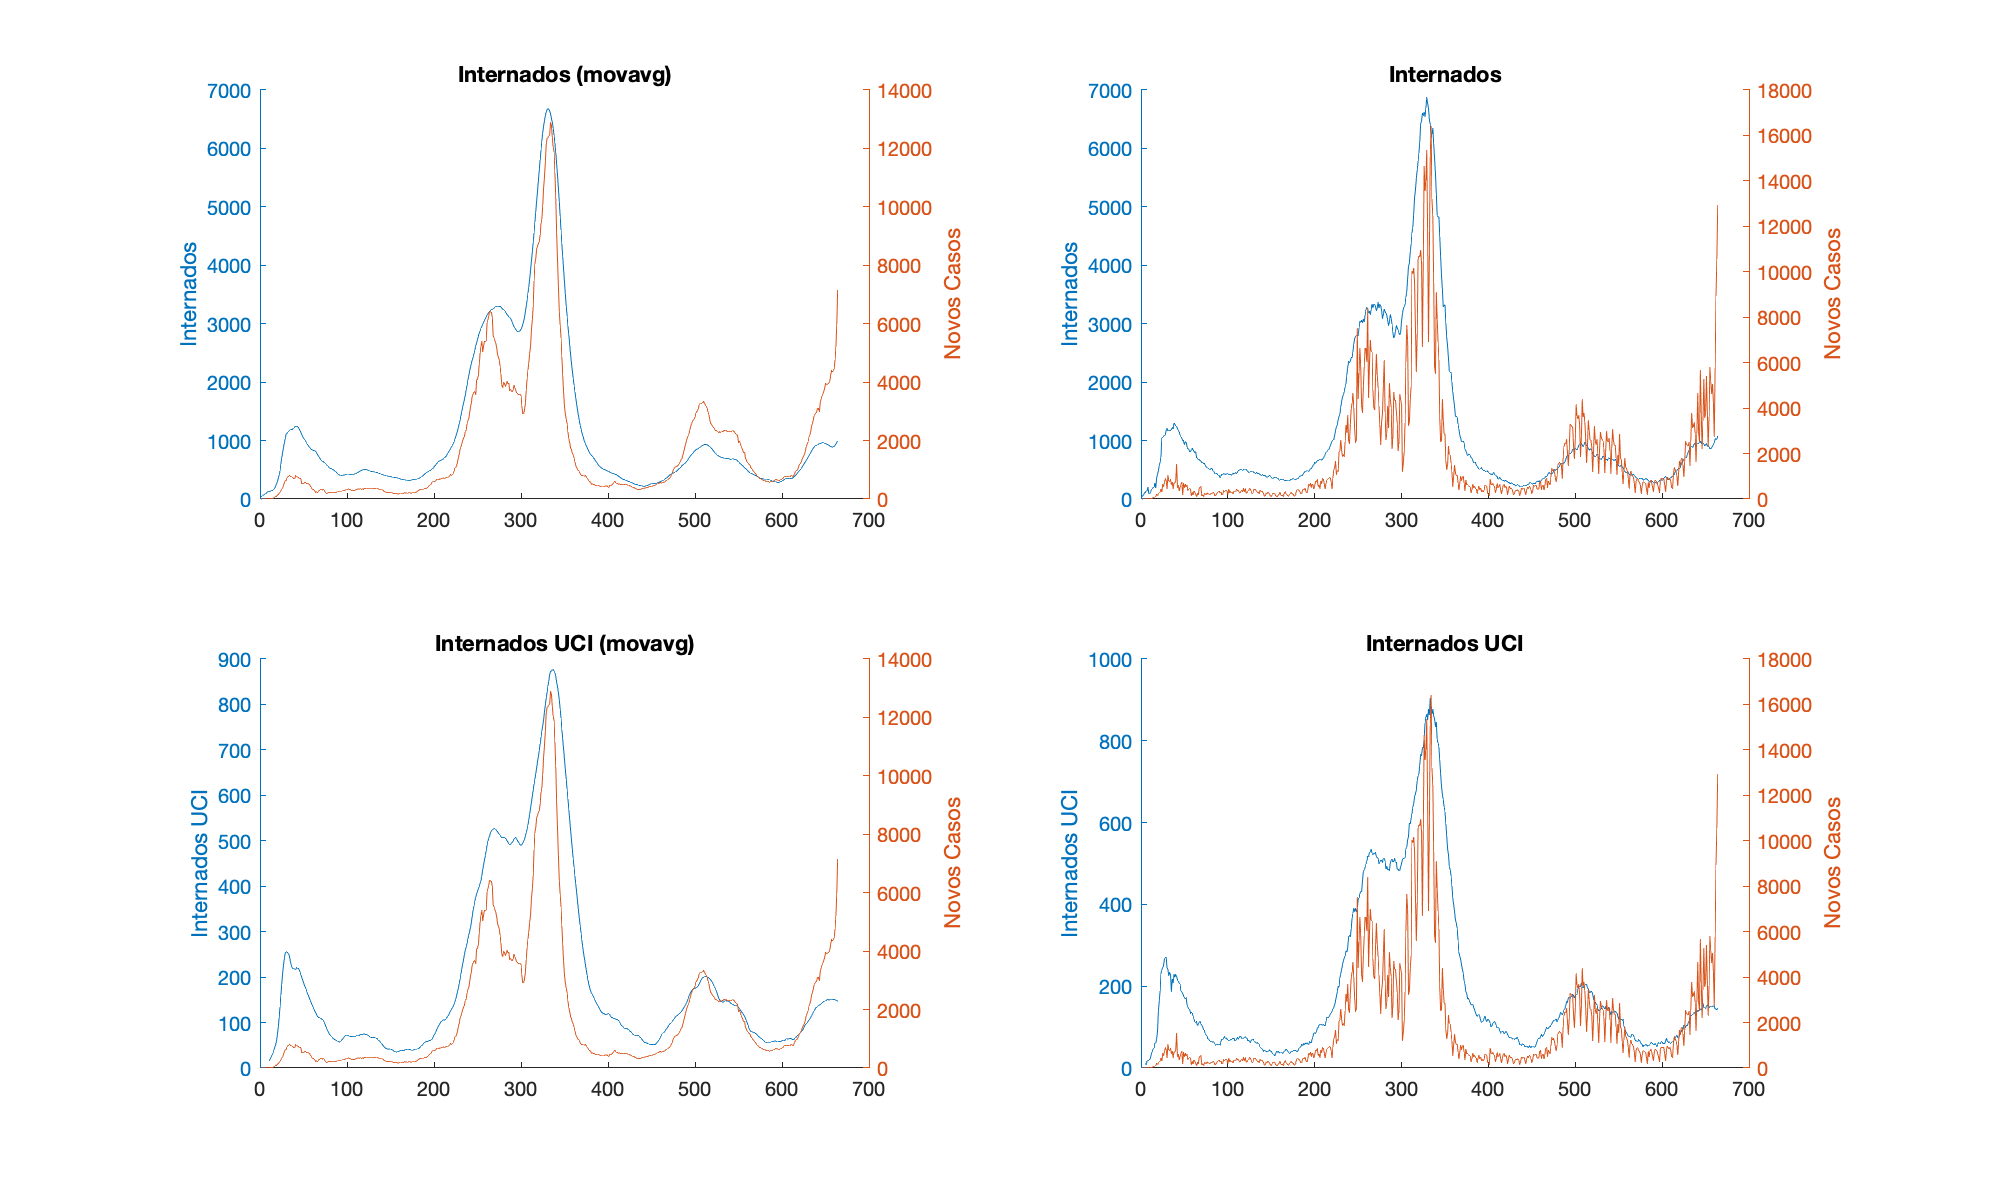

novos_casos = casos.confirmados_novos;
tamanho = size(novos_casos, 1);
novos_casos([tamanho-8,tamanho-7,tamanho-6,tamanho-5,tamanho-4,tamanho-3,tamanho-2,tamanho-1,tamanho], :) = [];
internados_uci = casos.internados_uci;
internados_uci([1,2,3,4,5,6,7,8,9], :) = [];
internados = casos.internados;
internados([1,2,3,4,5,6,7,8,9], :) = [];

f2 = figure();
%internados = (casos.internados_uci ./ amostras.amostras_novas);
subplot(2,2,1);
hold on
    title('Internados (movavg)');
    yyaxis left;
    ylabel('Internados');
    plot(movavg(internados, 'simple', 7));
    yyaxis right;
    ylabel('Novos Casos');
    plot(movavg(novos_casos, 'simple', 7));
hold off;
subplot(2,2,2);
hold on;
    title('Internados')
    yyaxis left;
    ylabel('Internados');
    plot(internados);
    yyaxis right;
    ylabel('Novos Casos');
    plot(novos_casos);
hold off;
%internados = (casos.internados_uci ./ amostras.amostras_novas);
subplot(2,2,3);
hold on
    title('Internados UCI (movavg)');
    yyaxis left;
    ylabel('Internados UCI');
    plot(movavg(internados_uci, 'simple', 7));
    yyaxis right;
    ylabel('Novos Casos');
    plot(movavg(novos_casos, 'simple', 7));
hold off;
subplot(2,2,4);
hold on;
    title('Internados UCI');
    yyaxis left;
    ylabel('Internados UCI');
    plot(internados_uci);
    yyaxis right;
    ylabel('Novos Casos');
    plot(novos_casos);
hold off;
set(f2, 'Position', [0 0 1000 600])

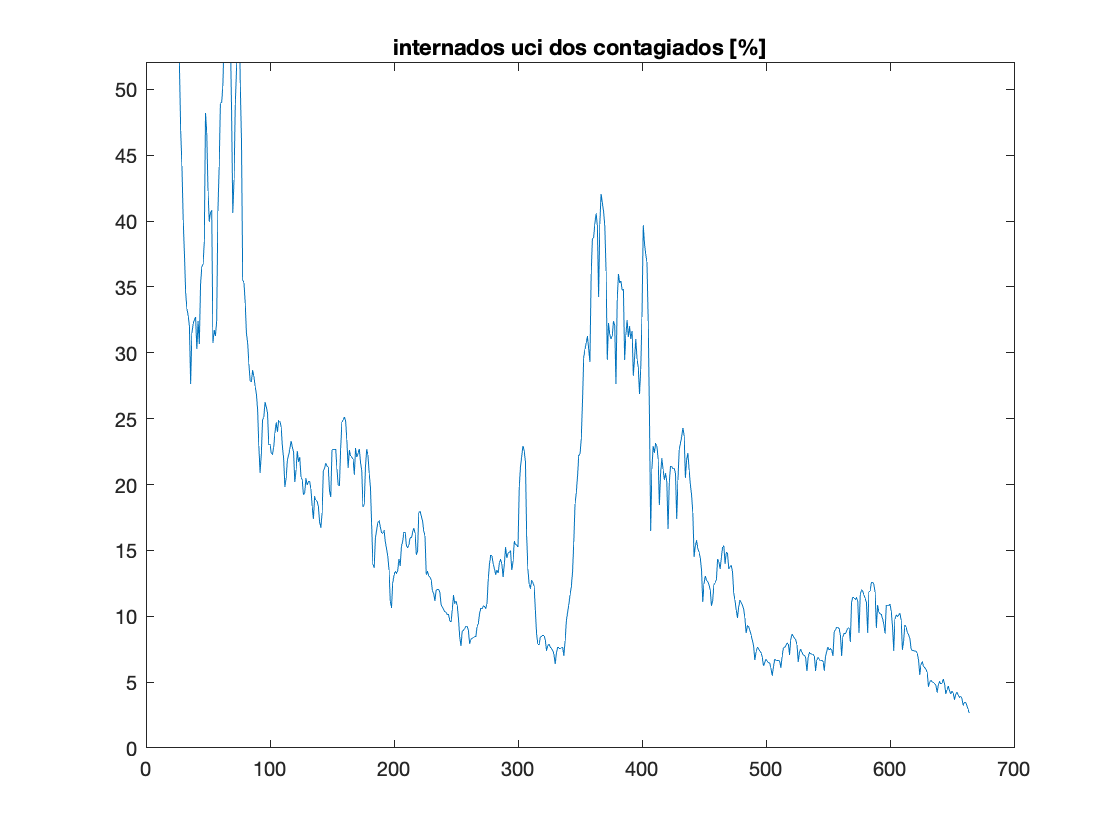

figure();
internados_uci = (internados_uci ./ novos_casos);
plot(movavg(internados_uci*100, 'simple', 6));
title('internados uci dos contagiados [%]');
ylim([0 52])